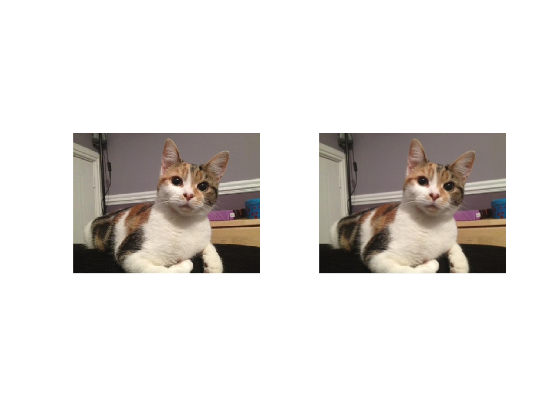

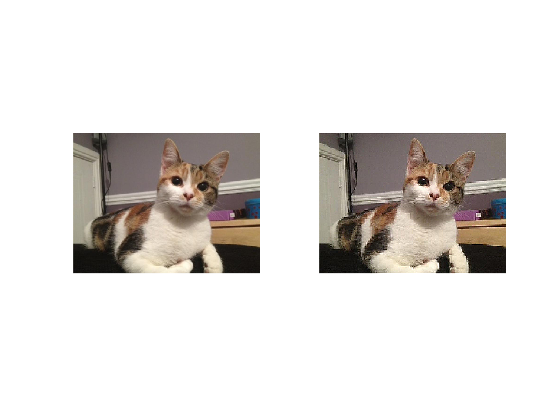

clear

img = imread('../images/cavendish.jpg');

image(img)
% Gaussian blur
n  = 5;
x = -floor(n / 2) : floor(n / 2);
sigma = 1;
gaussian = 1 / sqrt(2 * pi * sigma^2) * exp(- x.^2 / (2 * sigma^2));
blur = gaussian' * gaussian;
blur = blur ./ blur(1,1);
blur = blur ./ sum(sum(blur));

img_blur = img;
for i = 1 : 3
    img_blur(:,:,i) = conv2(img(:,:,i), blur, 'same');
end

subplot(1, 2, 1)
image(img)
axis equal off
axis([0, size(img,2), 0, size(img,1)])

subplot(1, 2, 2)
image(img_blur)
axis equal off
axis([0, size(img,2), 0, size(img,1)])

exportgraphics(gcf,'../images/cavendish_blur.png','Resolution',300) 

% Sharpen blur
figure()
sharpen = [0, -1, 0 ; -1, 5, -1 ; 0, -1, 0];

img_sharpen = img;
for i = 1 : 3
    img_sharpen(:,:,i) = conv2(img(:,:,i), sharpen, 'same');
end

subplot(1, 2, 1)
image(img)
axis equal
axis([0, size(img,2), 0, size(img,1)])
axis off

subplot(1, 2, 2)
image(img_sharpen)
axis equal
axis([0, size(img,2), 0, size(img,1)])
axis off

exportgraphics(gcf,'../images/cavendish_sharpen.png','Resolution',300) 